# Dirac Model

## Construct system


$$
    H=\sum_{ij}A_1 \left(a^\dag_{i+1,j}a_{i,j} +a_{i,j+1}^\dag a_{i,j}\right)+\sum_{ij}A_2 a_{i+1,j-1}^\dag a_{i,j}+c.c.+\beta\sum_{ij}\sigma_z a^\dag_{i,j}a_{i,j}
$$


function syst = Dirac_model(options)
% DIRAC_MODEL construct the Dirac model in hexagonal lattice.
% 
% Parameters
% ------
% t : the parm of next neighbour hopping
%     A1 = [0,t;-t*/2,0]; A2 = [0,-t/2;-t*/2,0].
% beta : Zeeman potential.
% N : size of lattice.
%
% Retuen
% ------
% syst : TB_Hamilton.Builder class.
arguments
    options.t (1,1)  = 4i/9;
    options.beta (1,1) = .1;
    options.N = .5;
end
[t,beta,N] = deal(options.t,options.beta,options.N);
vec = [-sqrt(3)/2 , 3/2; sqrt(3)/2,3/2];     % basic
basis = [0,0];
name = "A";
lat = TB_Hamilton.general(vec,name,basis,2);
lat.shape = polyshape(N*[0,-10*sqrt(3),0,10*sqrt(3),0],N*[0,30,60,30,0]-.5*ones(1,5));
syst = TB_Hamilton.Builder(lat,[1,0;0,1]);
sz = [1,0;0,-1];
lats={lat};

syst(TB_Hamilton.Builder.HoppingKind(lats{1},lats{1},[1,0])) = [0,t;-conj(t)/2,0];
syst(TB_Hamilton.Builder.HoppingKind(lats{1},lats{1},[0,1])) = [0,t;-conj(t)/2,0];
syst(TB_Hamilton.Builder.HoppingKind(lats{1},lats{1},[1,-1])) = [0,-t/2;-conj(t)/2,0];

syst(TB_Hamilton.Builder.HoppingKind(lats{1},lats{1},[0,0])) = beta * sz;
syst.finalized
end

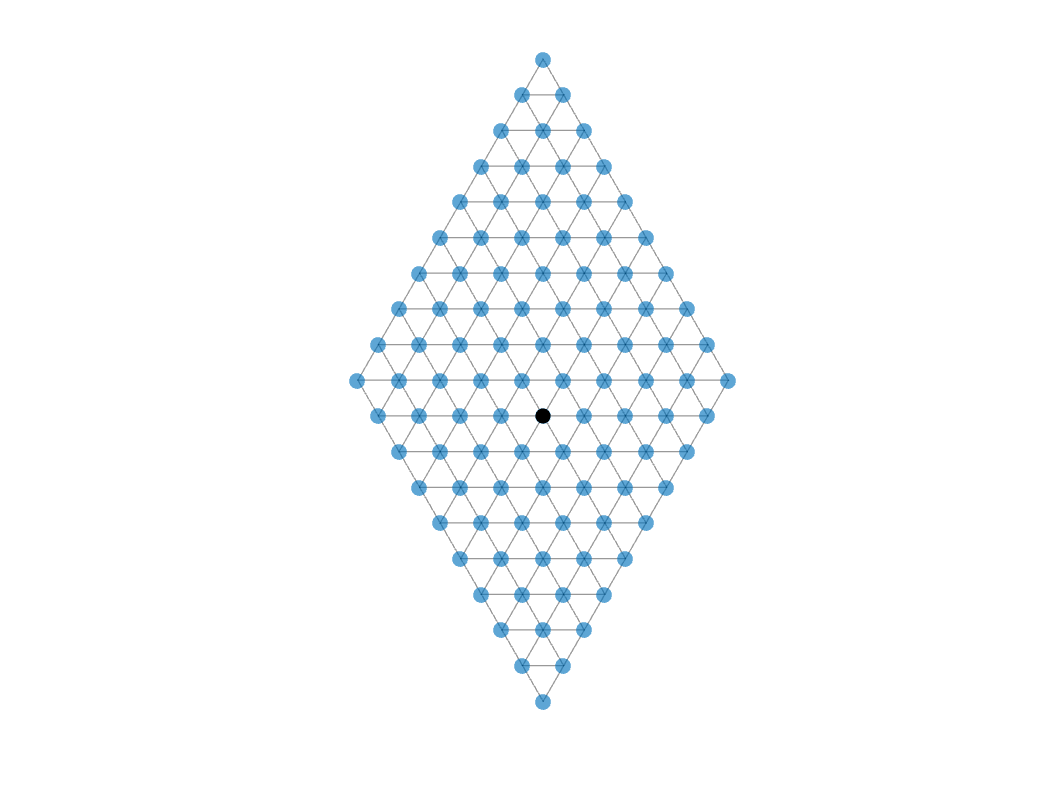

syst = Dirac_model();
figure
TB_Hamilton.Plot.ScatterRegion(syst,SizeData=40)
axis off

## Effective Model in K/K'

syms kx ky real;
% X_2
H = syst.Hamilton(kx-4*pi/(3*sqrt(3)),ky);
vpa(taylor(H,[kx,ky],[0,0],'order',2),3)

$$ans = \left(\begin{array}{cc} -0.1 & 1.0\,\mathrm{ky}-1.0\,\mathrm{kx}\,\mathrm{i}-4.73e-11\,\mathrm{i}\\ 1.0\,\mathrm{kx}\,\mathrm{i}+1.0\,\mathrm{ky}+4.73e-11\,\mathrm{i} & 0.1 \end{array}\right)$$

H = syst.Hamilton(kx+4*pi/(3*sqrt(3)),ky);
vpa(taylor(H,[kx,ky],[0,0],'order',2),3)

$$ans = \left(\begin{array}{cc} -0.1 & 1.0\,\mathrm{kx}\,\mathrm{i}+1.0\,\mathrm{ky}-4.73e-11\,\mathrm{i}\\ 1.0\,\mathrm{ky}-1.0\,\mathrm{kx}\,\mathrm{i}+4.73e-11\,\mathrm{i} & 0.1 \end{array}\right)$$

## Energy Band

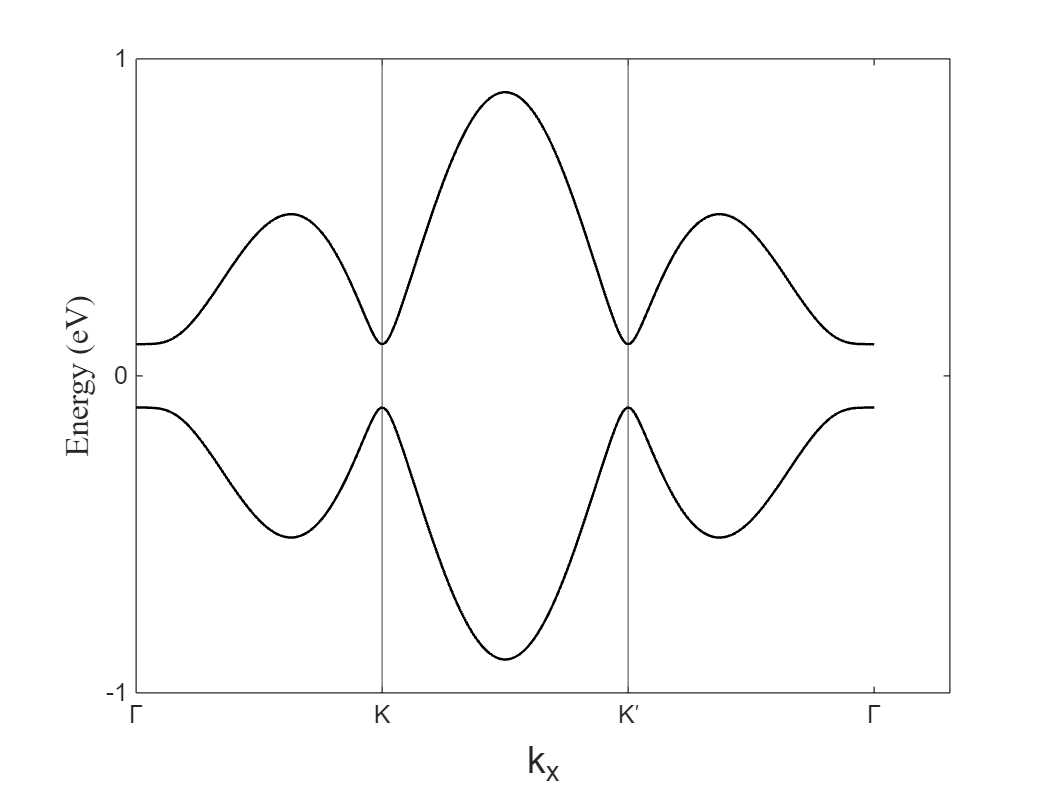

ky = 0;
kx = linspace(0,12*pi/(3*sqrt(3)),500);
Es = zeros(2,length(kx));
for j1 = 1:length(kx)
    H = full(syst.Hamilton(kx(j1),ky));
    Es(:,j1) = eig(H);
end
figure
plot(kx,Es,'k','LineWidth',1)
hold on
xline([4*pi/(3*sqrt(3)),8*pi/(3*sqrt(3))]);
xlabel('k_x','Fontsize',15);     ylabel({'Energy (eV)'},'FontSize',13,'FontName','Times');
xticks([0,4*pi/(3*sqrt(3)),8*pi/(3*sqrt(3)),12*pi/(3*sqrt(3))]);
xticklabels({'\Gamma','K','K^\prime','\Gamma'})
yticks([-1,0,1]);

# Zeeman Berry Curvature

clc;clear;
syst = Dirac_model();
kx = linspace(-pi/sqrt(3),pi/sqrt(3),3000*.8);
ky = linspace(0,4*pi/3,3000);
sx = [0,1;1,0]; sy =  [0,-1i;1i,0];
[Z_xy,Z_yx,Es] = TB_Hamilton.TopoNumber.Zeeman_curvature(syst,kx,ky,sx,sy,1:2); %% Z_xy = real(r^x s^y),Z_yx = real(r^y s^x)
ZA_xy = (Z_xy-Z_yx)/2;

mu = linspace(-2,2,500);
sigma = zeros(size(mu));
for j1 = 1:length(mu)
    id = Es<mu(j1);
    sigma(j1) = sum(ZA_xy(id));
end
% kx -- 3000, sigma in gap =0.06
% kx -- 2000, sigma in gap =0.1

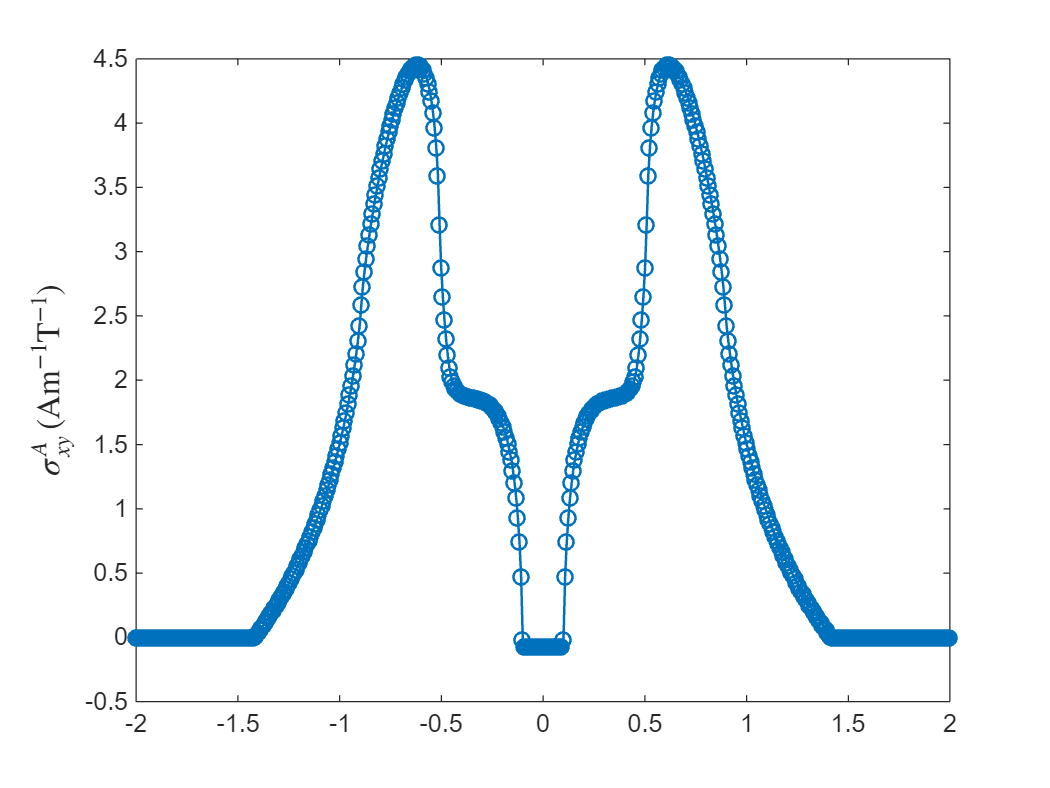

e = 1.602*1e-19;      %(A*s)
me = 9.109*1e-31;     % kg
hbar = 1.055*1e-34;   % m^2*kg/m
mu_B = e*hbar/(2*me);
sigma1 = e*mu_B/hbar*1e10*sigma/(4*pi^2);
figure
plot(mu,sigma1,'-o','linewidth',1)  %% The result in gap does not equal 0, because the number kx not ->infity
ylabel('$\sigma^A_{xy}\, \left(\mathrm{Am^{-1} T^{-1}}\right)$','Interpreter','latex','FontSize',13)

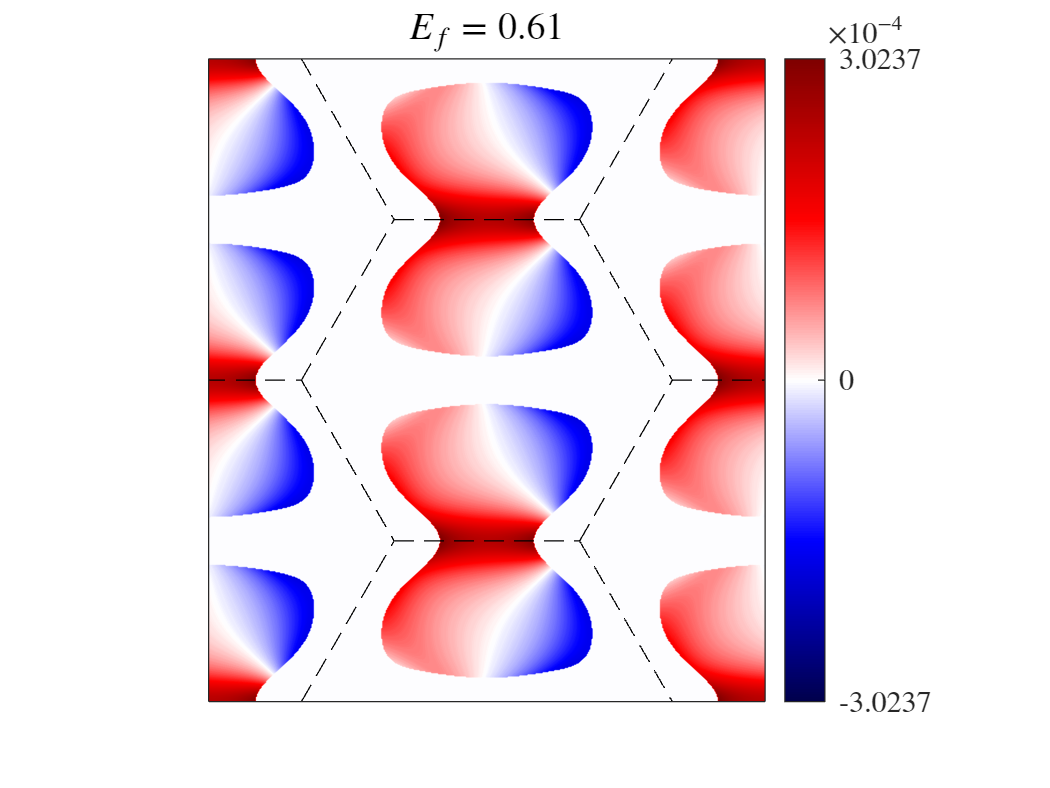

kx = 2*linspace(-pi/sqrt(3),pi/sqrt(3),600*.8);
ky = 2*linspace(0,4*pi/3,6*100);
mu = 0.61;
sx = [0,1;1,0]; sy =  [0,-1i;1i,0];
syst = Dirac_model();
[Z_xy,Z_yx] = TB_Hamilton.TopoNumber.Zeeman_curvature(syst,kx,ky,sx,sy,mu,'Energy'); %% Z_xy = real(r^x s^y),Z_yx = real(r^y s^x)
ZA_xy = (Z_xy-Z_yx)/2;
[Kx,Ky] = meshgrid(kx,ky);
figure
contourf(Kx,Ky,ZA_xy',256,'EdgeColor','none')
colormap(slanCM(104,256));
yticks([])
colorbar
hold on
TB_Hamilton.Plot.FBZ(syst,0)
axis([min(kx),max(kx),min(ky),max(ky)])
clim_min = -max(abs(ZA_xy(:))); clim_max = -clim_min;
clim([clim_min,clim_max]);
colorbar('Ticks',[clim_min,0,clim_max],'FontSize',12,'FontName','Times','TickLabelInterpreter','latex');
title("$E_f= " + num2str(mu) + "$",'Interpreter','latex','FontSize',15)